  clear 


x_moto = [5,0,9,7,1,6,3,8,4]

x_moto =      5     0     9     7     1     6     3     8     4


K = fix(log2(length(x_moto)))+1

K = 4


L = 2.^[0:K-1]

L =      1     2     4     8



x= zeros(1,1000);
x(1:length(x_moto))=x_moto;

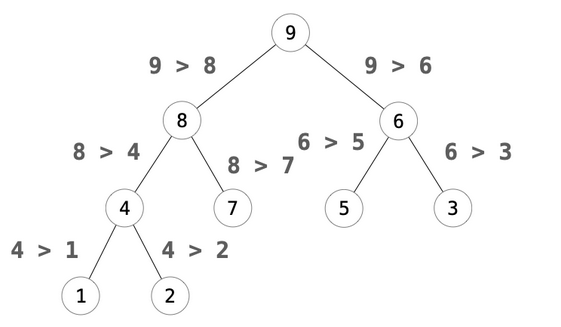

2分岐の作成


for l=2:length(L)
   for k=0:length(L)-1
       m=2*k;
       n=m+1;

        if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
            tmp = x(L(l)+m);
            x(L(l)+m) = x(L(l)+n);
            x(L(l)+n) = tmp;
        end

        if x(L(l-1)+k) < x(L(l)+m) % 上が大きいにする。
            tmp = x(L(l-1)+m);
            x(L(l-1)+k) = x(L(l)+m);
            x(L(l)+m) = tmp;
        end

   end

end

x

x =      9     8     6     7     1     3     1     4     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


トップを除く


x_result(1) = x(1)

x_result = 9

x(1) = -0;

x

x =      0     8     6     7     1     3     1     4     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for l=2:length(L)
   for k=0:length(L)-1
       m=2*k;
       n=m+1;

        if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
            tmp = x(L(l)+m);
            x(L(l)+m) = x(L(l)+n);
            x(L(l)+n) = tmp;
        end

        if x(L(l-1)+k) < x(L(l)+m) % 上が大きいにする。
            tmp = x(L(l-1)+m);
            x(L(l-1)+k) = x(L(l)+m);
            x(L(l)+m) = tmp;
        end

   end

end

x

x =      8     7     6     6     1     3     1     4     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


トップを除く


x_result(2) = x(1)

x_result =      9     8


x(1) = -1;

x

x =     -1     7     6     6     1     3     1     4     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for l=2:length(L)
   for k=0:length(L)-1
       m=2*k;
       n=m+1;

        if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
            tmp = x(L(l)+m);
            x(L(l)+m) = x(L(l)+n);
            x(L(l)+n) = tmp;
        end

        if x(L(l-1)+k) < x(L(l)+m) % 上が大きいにする。
            tmp = x(L(l-1)+m);
            x(L(l-1)+k) = x(L(l)+m);
            x(L(l)+m) = tmp;
        end

   end

end

x_result(3) = x(1)

x_result =      9     8     7


x(1) = -1;



x

x =     -1     6     6     6     1     3     1     4     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for l=2:length(L)
   for k=0:length(L)-1
       m=2*k;
       n=m+1;

        if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
            tmp = x(L(l)+m);
            x(L(l)+m) = x(L(l)+n);
            x(L(l)+n) = tmp;
        end

        if x(L(l-1)+k) < x(L(l)+m) % 上が大きいにする。
            tmp = x(L(l-1)+m);
            x(L(l-1)+k) = x(L(l)+m);
            x(L(l)+m) = tmp;
        end

   end

end

x_result(4) = x(1)

x_result =      9     8     7     6


x(1) = -1;



x

x =     -1     6     6     6     1     3     1     4     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for l=2:length(L)
   for k=0:length(L)-1
       m=2*k;
       n=m+1;

        if x(L(l)+m) < x(L(l)+n) % % 左が大きいにする。
            tmp = x(L(l)+m);
            x(L(l)+m) = x(L(l)+n);
            x(L(l)+n) = tmp;
        end

        if x(L(l-1)+k) < x(L(l)+m) % 上が大きいにする。
            tmp = x(L(l-1)+m);
            x(L(l-1)+k) = x(L(l)+m);
            x(L(l)+m) = tmp;
        end

   end

end

x_result(5) = x(1)

x_result =      9     8     7     6     6


x(1) = -1;